% read in table and format it to our liking.
clsTab=jellyfish.readClassification.import_classification_file_CJF('191121');

## separate the Phase 1 classification table

startDate=datetime('01/06/21 00:00','InputFormat',"dd/MM/yy HH:mm");
endDate=datetime('14/06/21 23:59','InputFormat',"dd/MM/yy HH:mm");

clsTabP1=jellyfish.readClassification.format_classification_table_CJF(clsTab,'start',startDate,'end',endDate);
%head(clsTab,5)
%clsTab=jellyfish.readClassification.simulationMask(clsTab,'TNG50');
% Classification info based on data downloaded on 14/7/21
% review and training set objecs classifications are removed.
% The raw classification data is reformatted into a new table with columns contiaing the snapshot, id  Id for the object as well as the label (jelly or not):

## Separaete the phase 2 classification table

startDate=datetime('22/08/21 00:00','InputFormat',"dd/MM/yy HH:mm");
endDate=datetime('19/11/21 23:59','InputFormat',"dd/MM/yy HH:mm");

clsTabP2=jellyfish.readClassification.format_classification_table_CJF(clsTab,'start',startDate,'end',endDate);

## concatenate the two phases

clsTab12=vertcat(clsTabP1,clsTabP2);

## Number of Inspections per Inspector 

cmap=brewermap(5,'Set1');

% Get the number of classifications per inspector
GC=groupcounts(clsTab12,'user_name');
GC1=groupcounts(clsTabP1,'user_name');
GC2=groupcounts(clsTabP2,'user_name');



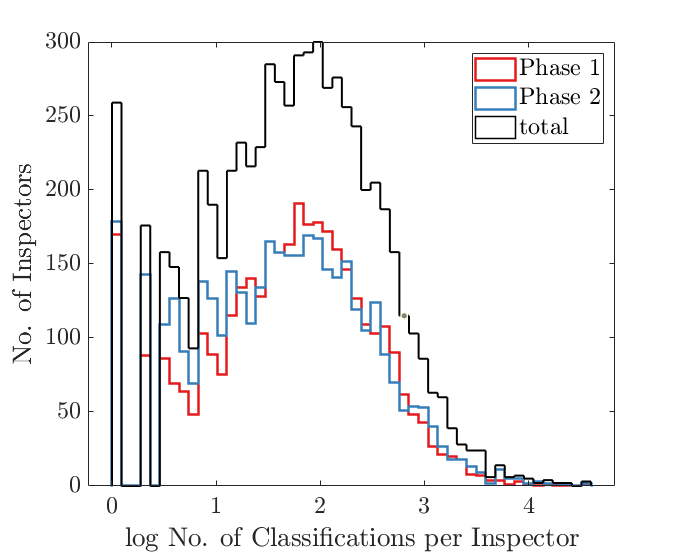


myFigure;
bn=50;
h(1)=histogram(log10(GC1.GroupCount),bn,'DisplayStyle','stairs','edgecolor',cmap(1,:),'linewidth',1.8,...
    'Displayname','Phase 1');
hold on
h(2)=histogram(log10(GC2.GroupCount),bn,'DisplayStyle','stairs','edgecolor',cmap(2,:),'linewidth',1.8,...
    'Displayname','Phase 2','facealpha',0.5);
h(3)=histogram(log10(GC.GroupCount),bn,'edgecolor','k','DisplayStyle','stairs','linewidth',1.2,......
    'DisplayNAme','total');
set(gca,'fontsize',18,'TickLabelInterpreter','latex')
legend(h,'Interpreter','latex','location','northeast','fontsize',18)
xlabelmine('log No. of Classifications per Inspector',20);
ylabelmine('No. of Inspectors',20);


fprintf('The average/median number of inspections in Phase I is: %f / %f',mean(GC1.GroupCount),median(GC1.GroupCount))

The average/median number of inspections in Phase I is: 211.061517 / 57.000000

fprintf('The average/median number of inspections in Phase II is: %f / %f',mean(GC2.GroupCount),median(GC2.GroupCount))

The average/median number of inspections in Phase II is: 268.279688 / 45.000000

fprintf('The average/median number of inspections overall is: %f / %f',mean(GC.GroupCount),median(GC2.GroupCount))

The average/median number of inspections overall is: 276.453957 / 45.000000

fprintf('No of Inspectors not logged in : %i',sum(GC.user_name.contains('not_logged_in')))

No of Inspectors not logged in : 2144

fprintf('No of classifications from not-logged-in Inspectors : %i (%4.2f %%)',...
    sum(GC.GroupCount(GC.user_name.contains('not_logged_in'))),...
    sum(GC.GroupCount(GC.user_name.contains('not_logged_in')))./sum(GC.GroupCount).*100);

No of classifications from not-logged-in Inspectors : 341727 (19.03 %)

19 % of classifications are from users not logged in. 

## who are the top Inspectors?


%ntop=sum(GC.GroupCount>=1000);
fprintf('There are %i Inspectrors with more than 1000 inspections',sum(GC.GroupCount>=1000))

There are 325 Inspectrors with more than 1000 inspections

fprintf('There are %i Inspectrors with more than 5000 inspections',sum(GC.GroupCount>=5000))

There are 44 Inspectrors with more than 5000 inspections

fprintf('There are %i Inspectrors with more than 10000 inspections',sum(GC.GroupCount>=10000))

There are 17 Inspectrors with more than 10000 inspections


topT=GC(GC.GroupCount>=5000,:);
[~,ix]=sort(topT.GroupCount,'descend');
topT(ix,:)

ans = 44×2 table
       user_name       GroupCount
    _______________    __________

    "ssh"                36703   
    "IworkAtCostco"      36102   
    "enhudgens"          32723   
    "Jujujulz"           22278   
    "CFiligenzi"         21273   
    "Get2david"          20927   
    "Sunrise1324"        17923   
    "Prothon"            15448   
    "ElisabethB"         15439   
    "planetari7"         14379   
    "stephanie79"        14228   
    "tharshini"          13794   
    "Jan225"             11569   
    "Yukirvan"           11108   
    "lamperti"           11081   
    "myrikhan"           10848   



fprintf('Total No. of Inspectors: %i',height(GC))

Total No. of Inspectors: 6494

fprintf('Total No. of classifications: %i',sum(GC.GroupCount))

Total No. of classifications: 1795292

fprintf('Top %i classifiers are responsible for %i classifications (%4.2f %%)',...
    sum(GC.GroupCount>=10000),sum(GC.GroupCount(GC.GroupCount>=10000)),...
    sum(GC.GroupCount(GC.GroupCount>=10000))./sum(GC.GroupCount).*100);

Top 17 classifiers are responsible for 316281 classifications (17.62 %)

fprintf('Top %i classifiers are responsible for %i classifications (%4.2f %%)',sum(GC.GroupCount>=5000),sum(topT.GroupCount),...
    sum(topT.GroupCount)./sum(GC.GroupCount).*100);

Top 44 classifiers are responsible for 491999 classifications (27.40 %)

fprintf('Top %i classifiers are responsible for %i classifications (%4.2f %%)',...
    sum(GC.GroupCount>=1000),sum(GC.GroupCount(GC.GroupCount>=1000)),...
    sum(GC.GroupCount(GC.GroupCount>=1000))./sum(GC.GroupCount).*100);

Top 325 classifiers are responsible for 1007680 classifications (56.13 %)

We see that a relatively small number (~ 5 %) of Inspectors are responsible for ~56% of classifications. If there are some 'idiots' in this group - they may have a large effect. 

## load object table

global DEFAULT_MATFILE_DIR
load([DEFAULT_MATFILE_DIR '/cosmic_jellyfish_objectTable.mat'],'objectTable','objectTablePref','objectTableComp');


## Generate an Inspector score 

We will generate an inspector score - based on how often the inspector votes differently than the majority. The higher/lower the overall score, the more the discrepancy will count. We'll do this for high and low scores separately and also for the combined 

% High scores (down-voters) 

% identify subject Id's 
ind1=find(objectTable.score>=10);
ind2=find(objectTablePref.score>=10 );
sidList=cat(1,objectTable.subject_ids(ind1),objectTablePref.subject_ids(ind2));

iscoreHigh=GC;
iscoreHigh.wt=zeros(size(iscoreHigh.user_name));
iscoreHigh.score=zeros(size(iscoreHigh.user_name));
iscoreHigh.ncls=zeros(size(iscoreHigh.user_name));

for i=1:length(sidList)
    clsInd=find(clsTab12.subject_ids==sidList(i)); % indices of classifications
    unames=clsTab12.user_name(clsInd);
    votes=clsTab12.isJelly(clsInd);
    
    wt=abs(2.0.*sum(votes)./length(votes)-1)
    %wt=sum(votes)./length(votes);

    [~,ii]=ismember(unames,GC.user_name);
    iscoreHigh.wt(ii)=iscoreHigh.wt(ii)+wt;
    iscoreHigh.score(ii)=iscoreHigh.score(ii)+wt.*votes;
    iscoreHigh.ncls(ii)=iscoreHigh.ncls(ii)+1;
end
iscoreHigh.score=iscoreHigh.score./iscoreHigh.wt;
iscoreHigh.score(iscoreHigh.ncls==0)=1;

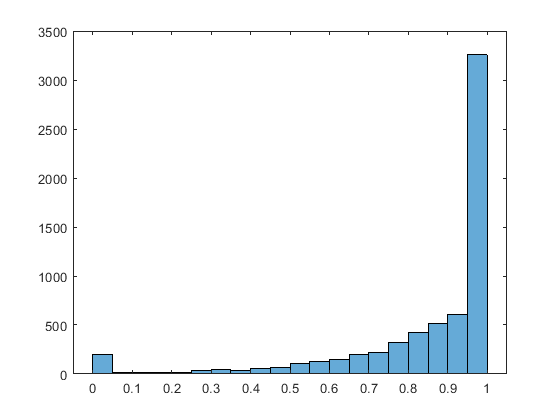

figure 
histogram(iscoreHigh.score,20)

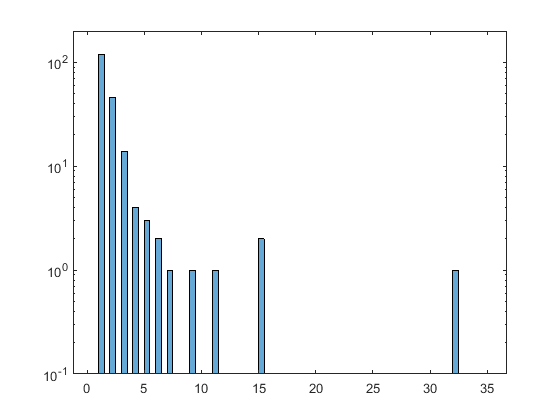


figure 
histogram(iscoreHigh.ncls(iscoreHigh.score==0),0.5:0.5:35)
set(gca,'yscale','log')
ylim([0.1 200])

% low scores (up-voters) 

% identify subject Id's 
ind1=find(objectTable.score<10);
ind2=find(objectTablePref.score<10 );
sidList=cat(1,objectTable.subject_ids(ind1),objectTablePref.subject_ids(ind2));

iscoreLow=GC;
iscoreLow.wt=zeros(size(iscoreLow.user_name));
iscoreLow.score=zeros(size(iscoreLow.user_name));
iscoreLow.ncls=zeros(size(iscoreLow.user_name));

for i=1:length(sidList)
    clsInd=find(clsTab12.subject_ids==sidList(i)); % indices of classifications
    unames=clsTab12.user_name(clsInd);
    votes=clsTab12.isJelly(clsInd);
    wt=1-sum(votes)./length(votes);

    [~,ii]=ismember(unames,GC.user_name);
    iscoreLow.wt(ii)=iscoreLow.wt(ii)+wt;
    iscoreLow.score(ii)=iscoreLow.score(ii)+wt.*(1-votes);
    iscoreLow.ncls(ii)=iscoreLow.ncls(ii)+1;
end
iscoreLow.score=iscoreLow.score./iscoreLow.wt;
iscoreLow.score(iscoreLow.ncls==0)=1;

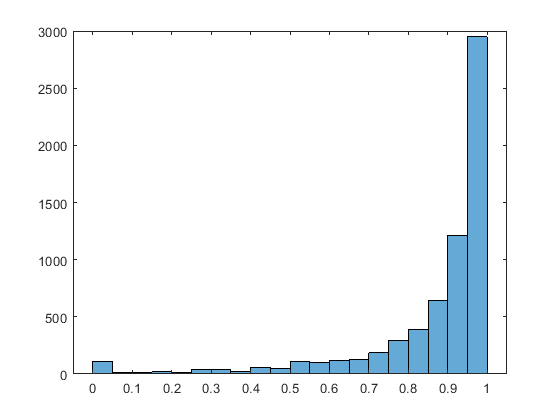

figure 
histogram(iscoreLow.score,20)

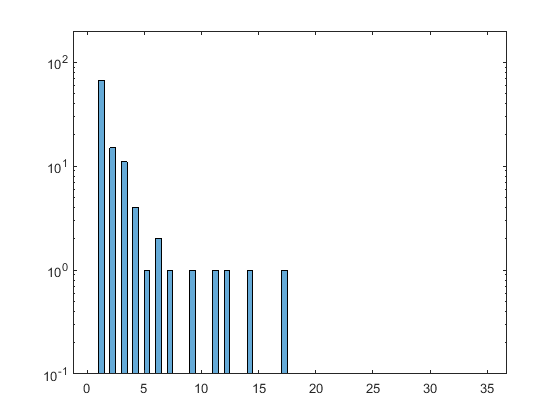


figure 
histogram(iscoreLow.ncls(iscoreLow.score==0),0.5:0.5:35)
set(gca,'yscale','log')
ylim([0.1 200])

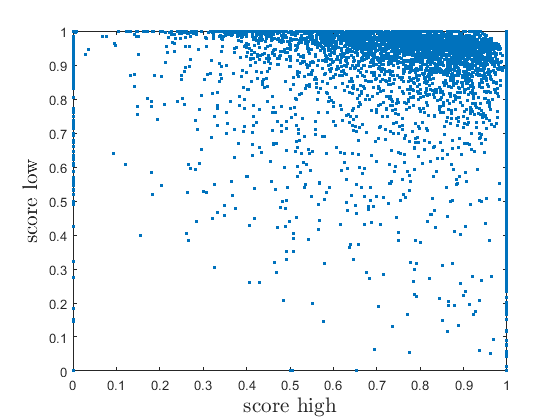



figure
plot(iscore.score,iscoreLow.score,'.' )
xlabelmine('score high');
ylabelmine('score low');


sum(iscore.score==0 & iscoreLow.score==0    )

ans =      5


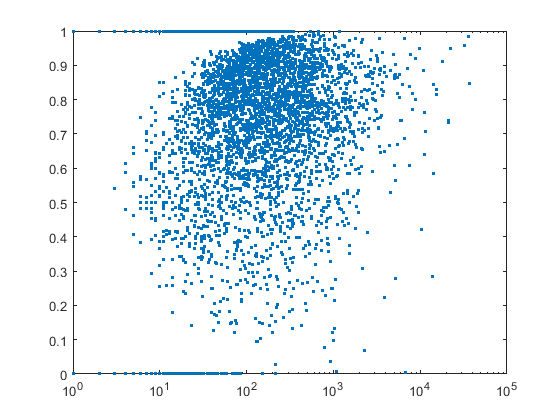


figure
semilogx(iscore.GroupCount,iscore.score,'.')    

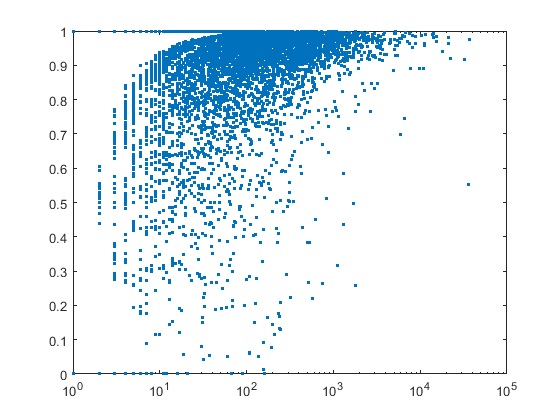

figure
semilogx(iscoreLow.GroupCount,iscoreLow.score,'.')    

% overall

% identify subject Id's 
%ind1=find(objectTable.score<10);
%ind2=find(objectTablePref.score<10 );
sidList=cat(1,objectTable.subject_ids(:),objectTablePref.subject_ids(:));

iscore=GC;
iscore.wt=zeros(size(iscore.user_name));
iscore.score=zeros(size(iscore.user_name));
iscore.ncls=zeros(size(iscore.user_name));

for i=1:length(sidList)
    clsInd=find(clsTab12.subject_ids==sidList(i)); % indices of classifications
    unames=clsTab12.user_name(clsInd);
    votes=clsTab12.isJelly(clsInd);
    
    wt=sum(votes)./length(votes);
    vv=votes;
    if wt<0.5
        wt=1-wt
        vv=1-vv;
    end

    [~,ii]=ismember(unames,GC.user_name);
    iscore.wt(ii)=iscore.wt(ii)+wt;
    iscore.score(ii)=iscore.score(ii)+wt.*(1-votes);
    iscore.ncls(ii)=iscore.ncls(ii)+1;
end
iscore.score=iscore.score./iscore.wt;
%iscore.score(iscore.ncls==0)=1;

## Older version - Find down-Voters

Down voters are Inspectors which consistently vote lower than others . We look at objects with scores of 15 and above and look for inspectors who voted 'NO' for these objects. Inspectors which voted in this way more than X times and above a given fraction of their votes on such objects will be labeled 'down-voters'. 



% identify relavent subject-ids
ind1=find(objectTable.score>=11 & objectTable.score<20);
ind2=find(objectTablePref.score>=11 & objectTablePref.score<20);
sidList1=objectTable.subject_ids(ind1);
sidList2=objectTablePref.subject_ids(ind2);

subject id's are unique - no overlap! 

sidList=cat(1,sidList1,sidList2);
GC.total_hiScore_votes=zeros(size(GC.user_name));
GC.downVotes=zeros(size(GC.user_name));
GC.downVoteScore=zeros(size(GC.user_name));
over20.inds=[];
over20.total=[];
over20.score=[];

for i=1:length(sidList)
    clsInd=find(clsTab12.subject_ids==sidList(i)); % indices of classifications
    unames=clsTab12.user_name(clsInd);
    votes=clsTab12.isJelly(clsInd);
    dvotes=~votes;
       
       
    [~,ii]=ismember(unames,GC.user_name);
    GC.total_hiScore_votes(ii)=GC.total_hiScore_votes(ii)+1;
    GC.downVotes(ii)=GC.downVotes(ii)+~votes;
    GC.downVoteScore(ii)=GC.downVoteScore(ii)+dvotes./sum(dvotes);
    
    if length(clsInd)>20
        over20.inds(end+1)=i;
        over20.total(end+1)=length(clsInd);
        over20.score(end+1)=sum(votes);
    end

end
    
   

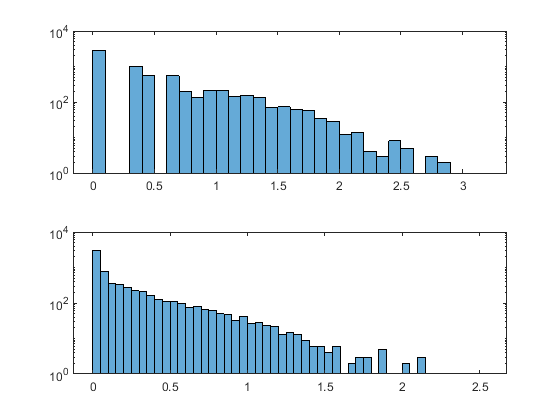


figure
t=tiledlayout('flow');
nexttile
histogram(log10(GC.downVotes+1))
set(gca,'yscale','log')
nexttile
histogram(log10(GC.downVoteScore+1))
% nexttile
% histogram(log10(GC.downVotes./))
set(gca,'yscale','log')

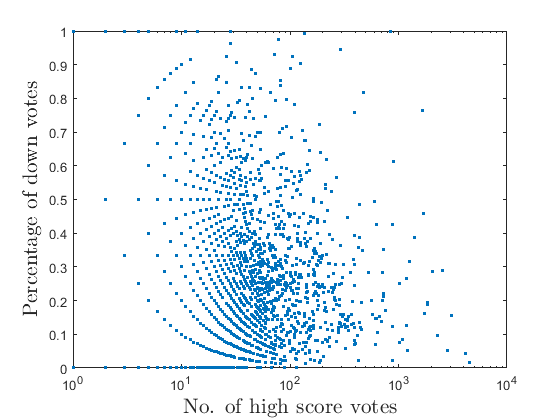

figure
semilogx      (GC.total_hiScore_votes,GC.downVotes./GC.total_hiScore_votes,'.')
   xlabelmine('No. of high score votes' );
   ylabelmine('Percentage of down votes');

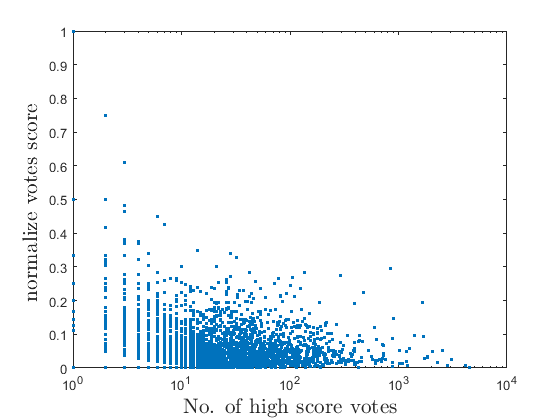

ans =   Text (normalize votes score ) with properties:

                 String: 'normalize votes score '
               FontSize: 16
             FontWeight: 'normal'
               FontName: 'Helvetica'
                  Color: [0.150000000000000 0.150000000000000 0.150000000000000]
    HorizontalAlignment: 'center'
               Position: [0.548104405062408 0.500000476837158 -1]
                  Units: 'data'

  Show all properties


   
   figure
semilogx      (GC.total_hiScore_votes,GC.downVoteScore./GC.total_hiScore_votes,'.')
   xlabelmine('No. of high score votes' );
   ylabelmine('normalize votes score ');

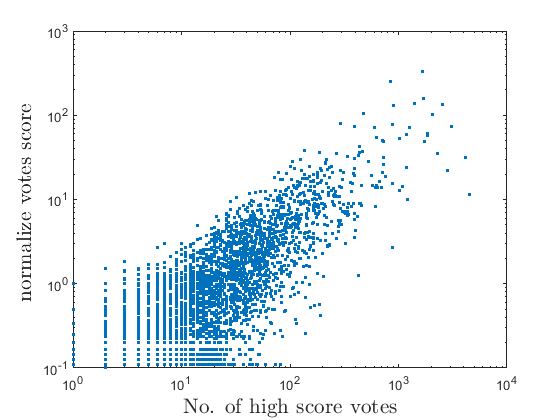

ans =   Text (normalize votes score ) with properties:

                 String: 'normalize votes score '
               FontSize: 16
             FontWeight: 'normal'
               FontName: 'Helvetica'
                  Color: [0.150000000000000 0.150000000000000 0.150000000000000]
    HorizontalAlignment: 'center'
               Position: [0.482573817270747 10.000043918421742 -1]
                  Units: 'data'

  Show all properties


   
   
   figure
   loglog(GC.total_hiScore_votes,GC.downVoteScore,'.')
   xlabelmine('No. of high score votes' );
   ylabelmine('normalize votes score ');

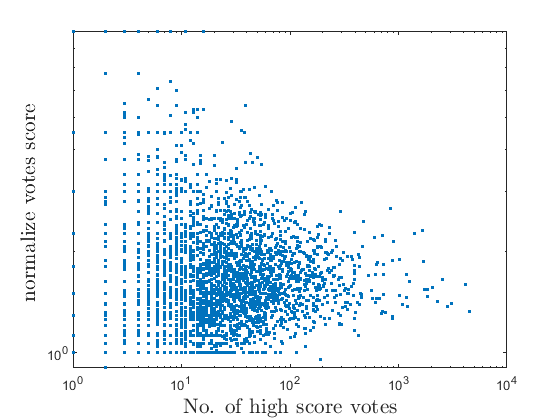

ans =   Text (normalize votes score ) with properties:

                 String: 'normalize votes score '
               FontSize: 16
             FontWeight: 'normal'
               FontName: 'Helvetica'
                  Color: [0.150000000000000 0.150000000000000 0.150000000000000]
    HorizontalAlignment: 'center'
               Position: [0.525327472566447 2.846053018996884 -1]
                  Units: 'data'

  Show all properties


   
   figure
   loglog(GC.total_hiScore_votes,GC.downVoteScore./(GC.downVotes/9),'.')
   xlabelmine('No. of high score votes' );
   ylabelmine('normalize votes score ')

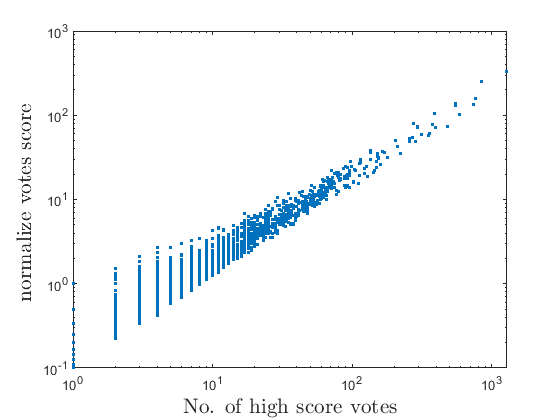

ans =   Text (normalize votes score ) with properties:

                 String: 'normalize votes score '
               FontSize: 16
             FontWeight: 'normal'
               FontName: 'Helvetica'
                  Color: [0.150000000000000 0.150000000000000 0.150000000000000]
    HorizontalAlignment: 'center'
               Position: [0.567689820831884 10.000043918421742 -1]
                  Units: 'data'

  Show all properties



    figure
   loglog(GC.downVotes,GC.downVoteScore,'.')
   xlabelmine('No. of high score votes' );
   ylabelmine('normalize votes score ');